#  Inverse Vektoriteration

Wir betrachten die Matrix

$A= \pmatrix{ 5 &4& 4& 5& 6 \cr 0& 8& 5& 6 &7 \cr 0 & 0 & 6 & 7& 8 \cr 0 & 0& 0 & -4 & 9 \cr 0&0&0&0 & -2}, \quad$mit Eigenwerten 5, 8, 6, -4, -2.

A=zeros(5,5);
A(1,1)=5; A(1,2)=4; A(1,3)=4; A(1,4)=5; A(1,5)=6;
          A(2,2)=8; A(2,3)=5; A(2,4)=6; A(2,5)=7;
                    A(3,3)=6; A(3,4)=7; A(3,5)=8;
                             A(4,4)=-4; A(4,5)=9;
                                       A(5,5)=-2;

 Wir wählen den Spektralverschiebungsparameter $\mu$ (siehe Buch) und die Anzahl der Iterationen $k_\max$:

mu=7.6

mu = 7.6000

kmax=10;

Die inverse Vektoriteration mit Spektralverschiebung $\mu$ wird durchgeführt und in jeder Iteration werden die berechnete Eigenwertannäherung $\lambda^{(k)}$, und (ab der dritten Iteration) die Fehlerschätzung

        $\frac{q_k}{1-q_k}\big(\lambda^{(k)}-\lambda^{(k-1)}\big), \quad \text{mit}~~q_k:=\frac{\lambda^{(k)}-\lambda^{(k-1)}}{\lambda^{(k-1)}-\lambda^{(k-2)}}
$,

gezeigt.

# Aktivität:

Variieren Sie den Spektralverschiebungsparameter $\mu$ und untersuchen Sie die Konvergenz(geschwindigkeit) des Verfahrens. Was passiert, wenn man den Parameterwert exakt in der Mitte zwischen zwei Eigenwerten wählt (z.B. $\mu=7$)?

y=ones(5,1);y=y/norm(y);
I=eye(5,5);
lambda=zeros(kmax,1);
format short;
for k=1:kmax
    Iteration=k
    ynew=(A-mu*I)\y;
    Approximation=1/(y'*ynew)+mu
    lambda(k)=Approximation;
    y=ynew/norm(ynew);
    if (k>=3)
      %  format short;
        q=(lambda(k)-lambda(k-1))/(lambda(k-1)-lambda(k-2))
     %   format shorte;
        Fehlerschaetzung=q/(1-q)*(lambda(k)-lambda(k-1))  
    end
    disp('----------------');
end

Iteration = 1

Approximation = 7.6705

----------------


Iteration = 2

Approximation = 8.1483

----------------


Iteration = 3

Approximation = 7.9640

q = -0.3857

Fehlerschaetzung = 0.0513

----------------


Iteration = 4

Approximation = 8.0097

q = -0.2479

Fehlerschaetzung = -0.0091

----------------


Iteration = 5

Approximation = 7.9975

q = -0.2670

Fehlerschaetzung = 0.0026

----------------


Iteration = 6

Approximation = 8.0006

q = -0.2550

Fehlerschaetzung = -6.3243e-04

----------------


Iteration = 7

Approximation = 7.9998

q = -0.2543

Fehlerschaetzung = 1.6051e-04

----------------


Iteration = 8

Approximation = 8.0000

q = -0.2523

Fehlerschaetzung = -4.0234e-05

----------------


Iteration = 9

Approximation = 8.0000

q = -0.2515

Fehlerschaetzung = 1.0092e-05

----------------


Iteration = 10

Approximation = 8.0000

q = -0.2509

Fehlerschaetzung = -2.5272e-06

----------------


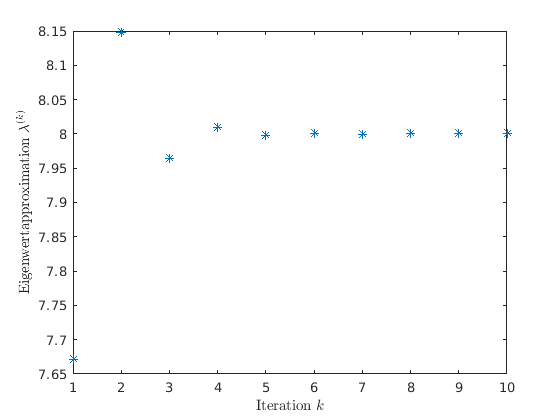

plot(lambda,'*')
xlabel('Iteration $k$','Interpreter','latex');   ylabel('Eigenwertapproximation $\lambda^{(k)}$','Interpreter','latex');